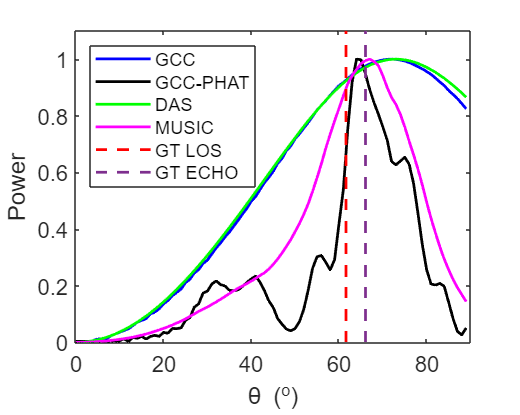

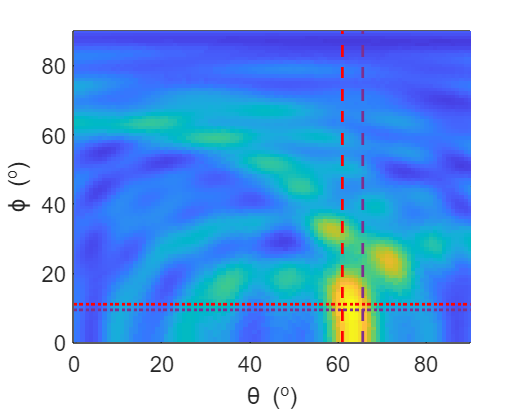

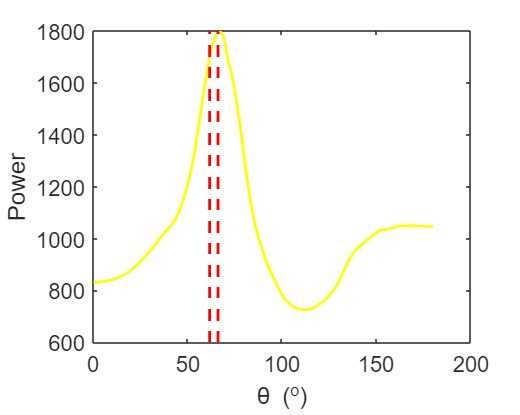

%%% only azimuth AOA
d_a = 0.05;
theta_range = 0:180;
y_arr = load('dw_4_s_60_41.txt');
theta1 = atan(37/20)/pi*180; theta2 = atan(45/20)/pi*180; 
% y_arr = load('dw_4_s_60_10.txt'); % dw_4_s_76_21
% theta1 = atan(6/20)/pi*180; theta2 = atan(14/20)/pi*180; 

% y_arr = [y_arr(:,1), y_arr(:,3)];
AOASpec_1 = gccphatAOASpectrum(y_arr, d_a); AOASpec_1 = mat2gray(AOASpec_1(1:90));
AOASpec_2 = xcorrAOASpectrum(y_arr, d_a); AOASpec_2 = mat2gray(AOASpec_2(1:90));
AOASpec_3 = DSBAOASpectrum(y_arr, d_a); AOASpec_3 = mat2gray(AOASpec_3(1:90));
AOASpec_4 = MUSICAoA(y_arr, d_a); AOASpec_4 = mat2gray(AOASpec_4(1:90));

figure(); hold on; box on; 
xlim([0,90]); ylim([0,1.1])
p1 = plot(theta_range(1:90), AOASpec_2, 'b', 'linewidth', 1.5);
p2 = plot(theta_range(1:90), AOASpec_1, 'k', 'linewidth', 1.5);
p3 = plot(theta_range(1:90), AOASpec_3, 'g', 'linewidth', 1.5);
p4 = plot(theta_range(1:90), AOASpec_4, 'color', 'm', 'linewidth', 1.5);
l1 = line([theta1,theta1],ylim, 'color', 'r', 'linewidth', 1.5, 'linestyle', '--');
l2 = line([theta2,theta2],ylim, 'color', '#7E2F8E', 'linewidth', 1.5, 'linestyle', '--');
legend([p1,p2, p3,p4,l1,l2], 'GCC', 'GCC-PHAT', 'DAS', 'MUSIC', 'GT LOS', 'GT ECHO', 'FontSize',10,'FontName', 'Arial', 'location', 'northwest', 'NumColumns',1)%, 'box', 'off' outside
xlabel('\theta (^o)','FontSize',12,'FontName', 'Arial')
ylabel('Power','FontSize',12,'FontName', 'Arial')
set(gca,'FontSize',12,'FontName', 'Arial');
set(gcf,'Units','centimeters','Position',[1.4 10 10 8])
hold off;